# Create App

This example shows how to use the **Generate JavaScript using MATLAB Coder** add-on to create a basic web application with a user interface that runs entirely in a web browser.

## Set Up the App Project

1. In the MATLAB® current folder browser, navigate to a folder where you can create and store your app project and files. 

2. Create the app project by entering this code in MATLAB command line. Specify a name and the directory for your app.

proj = wasm.project.create("MyNewApp","Language","C++","Type","Executable");

3. Create and add a new function, `foo.m`, to the project. This function prints the statement "Hello World!" in the Console using the wasm.console.log function.

4. Drag the label from **Labels > EntryPoint > Primary Function** onto the foo function. This labels the `foo` function as the main entry point for the app.

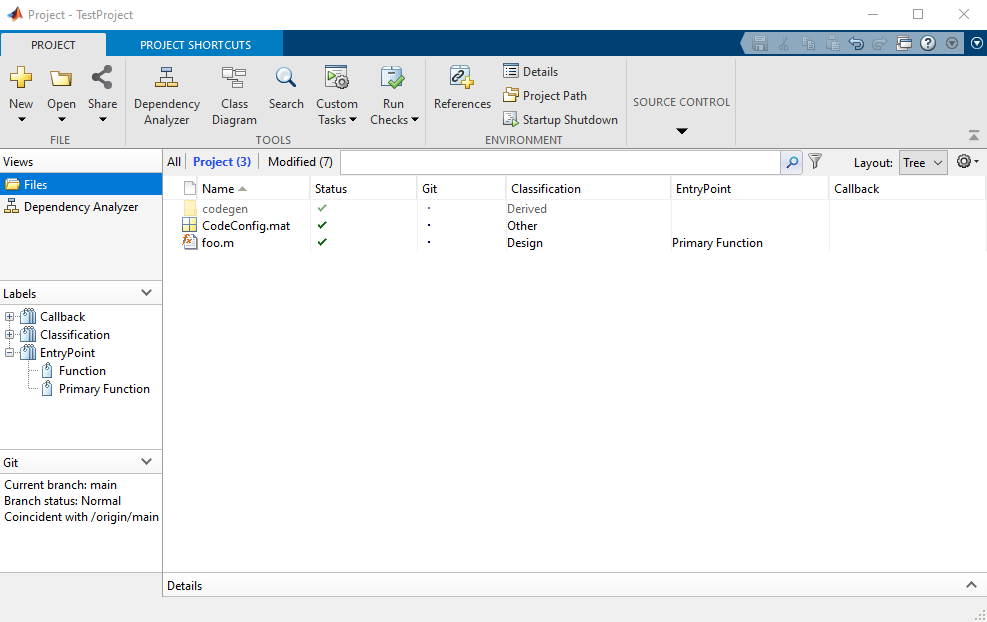

## Build the App

To build the app project, enter this code at the command prompt. The amount of time it take for the app to build depends on your host computer.

proj = openProject(pwd);
wasm.project.build(proj);

The resulting app is the set of 4 files located in the `dist` folder. 

Add a minimal index.html file to the project to run the generated JavaScript and WebAssembly code.

## Run the App

From the MATLAB command line, you can launch the app in a local server. To create the server and launch the app in the `dist` folder, enter this code.

server = wasm.utilities.DevelopmentServer("Directory",pwd,"Port",8000);
start(server);

Stop the server at any time using this command.

stop(server);

In a modern web browser, you can open the app by navigating to this IP address: [http://localhost:8000](http://localhost:8000). After the web page opens as a blank screen, open the browser developer tools by pressing **Ctrl+Shift+i**. The Console window displays the output of the s`tart` and r`ender` functions.